## Set up

clc
clear
clf
rng(16);

### Preprocessing

FullSet = readtable("process_model\generated_data_take2\training\Noisy\measured_data_combined.csv");
X = FullSet(:,2:3);
X.f_LO_measured = FullSet.f_LO_measured;
X.f_LE_measured = FullSet.f_LE_measured;
X.c_RaffP_measured = FullSet.c_RaffP_measured;
X.c_RaffS_measured = FullSet.c_RaffS_measured;
X.c_BO_measured = FullSet.c_BO_measured;

X_N = normalize(X);

y = FullSet.fault_state;

### kNN CV

k_values = [1:10, linspace(20,200, 19)];
cv_accuracies = zeros(1,length(k_values));
k_fold = 5;
cv = cvpartition(length(y), 'KFold', k_fold);

for i = 1:length(k_values)
    k = k_values(i);
    accuracies = zeros(1, k_fold);
    
    for fold = 1:k_fold
        trn = training(cv, fold);
        tst = test(cv, fold);
        
        X_train = X_N(trn, :);
        y_train = y(trn);
        X_test = X_N(tst, :);
        y_test = y(tst);
        
        % Train kNN for current k
        kNN_model = fitcknn(X_train, y_train, 'NumNeighbors', k);
        
        y_pred = predict(kNN_model, X_test);
        
        accuracy = sum(y_pred == y_test) / length(y_test);
        accuracies(fold) = accuracy;
        
    end
    
    cv_accuracies(i) = mean(accuracies);
end
[M, I] = max(cv_accuracies);
best_k = k_values(I);

disp(['Best k: ', num2str(best_k)]);

Best k: 3


disp(['Cross validation accuracy with best k: ', num2str(M)]);

Cross validation accuracy with best k: 0.99447


% train final kNN model
final_kNN_model = fitcknn(X_train,y_train, 'NumNeighbors', 3);

### kNN Confusion Charts

% Predict on the test data and calculate the confusion matrix
[y_pred_kNN, scores_kNN, cost_kNN] = predict(final_kNN_model, X_test);
kNN.c = confusionmat(y_test, y_pred_kNN);
disp('kNN Confusion Matrix:');

kNN Confusion Matrix:


disp(kNN.c);

       68264          47           8          22          69          77
          67       16760           0           0           0           0
           9           0        3870           0           0           0
          16           0           0       12324           0           0
         132           0           0           0         582           0
         155           0           0           0           0        1279



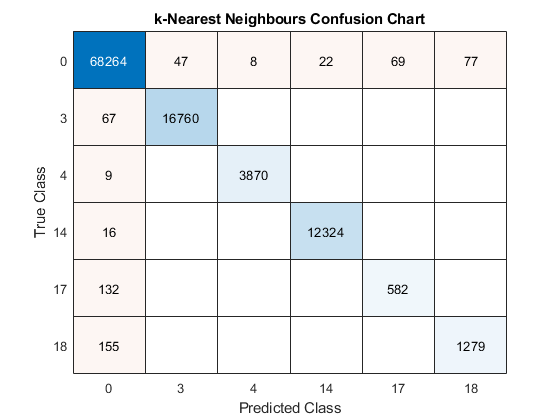


confusionchart(y_test, y_pred_kNN)
title('k-Nearest Neighbours Confusion Chart');
print('process_model/generated_data_take2/training/Noisy/Testing/kNN_2comp_confchart', '-dpng', '-r600')

mean(y_pred_kNN == y_test)

ans = 0.9942


kNN.c = confusionmat(y_test, y_pred_kNN);
kNN.c_correct = diag(kNN.c);
kNN.c_correct_sq = [zeros(5, 1) diag(kNN.c_correct(2:end))];
kNN.c_faulty = kNN.c(2:end, :);
kNN.TP = sum(kNN.c_correct_sq, "all");
kNN.false = kNN.c - diag(kNN.c_correct);
kNN.FP = sum(kNN.false(:, 2:end), "all");
kNN.FN = sum(kNN.c(2:end, 1));
kNN.TN = kNN.c(1,1);
kNN.precision = kNN.TP/(kNN.TP+kNN.FP);
kNN.sensitivity = kNN.TP/(kNN.TP+kNN.FN);
kNN.specificity = kNN.TN/(kNN.TN+kNN.FP);

### Save results

results = table();
results.labels = ["Precision"; "Sensitivity"; "Specificity"];
results.kNN_value = [kNN.precision; kNN.sensitivity; kNN.specificity];
writetable(results, "process_model/generated_data_take2/training/Noisy/Testing/kNN_results.csv");


accuracy_chart = table();
accuracy_chart.k_vals = k_values;
accuracy_chart.accuracy = cv_accuracies;

writetable(accuracy_chart, "process_model/generated_data_take2/training/Noisy/Testing/kNN_accuracies.csv");

### ROC Curves

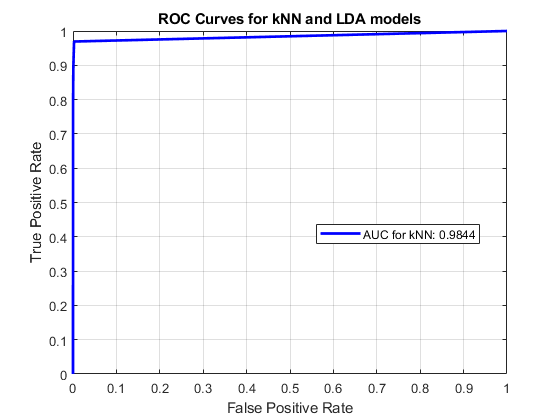

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
current = 18;
labels_binary_kNN = y_test;
labels_binary_kNN(labels_binary_kNN == current) = 1;
labels_binary_kNN(labels_binary_kNN ~= 1) = 0;

sum_scores_kNN = sum(scores_kNN(:, 2:end), 2);

% Calculate the ROC curve and AUC for kNN kernel
[X_roc_kNN, Y_roc_kNN, ~, AUC_kNN] = perfcurve(labels_binary_kNN, scores_kNN(:, 6), 1);

% Plot the ROC curves for both kernels
figure;
plot(X_roc_kNN, Y_roc_kNN, 'b-', 'LineWidth', 2);
hold on;
xlabel('False Positive Rate');
ylabel('True Positive Rate');
title('ROC Curves for kNN and LDA models');
legend(['AUC for kNN: ', num2str(AUC_kNN)], 'Location', 'Best');
grid on;
hold off;
print('process_model/generated_data_take2/training/Noisy/Testing/kNN_ROC_fault18_test', '-dpng', '-r600')